clc
clear 
close all

load helidata
vib = vib - mean(vib);  % Remove the DC component 

## 时频图1

% 这个直接画，或者和下面那样先得出数据再画
% 这个可以互动
%  rpmfreqmap(vib,fs,rpm);

## 时频图2

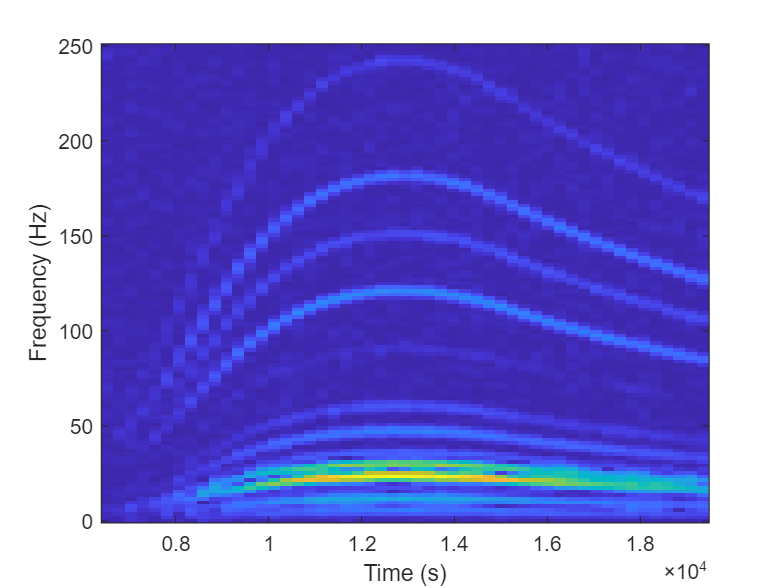

[map,freq,rpmOut,time] = rpmfreqmap(vib,fs,rpm);
figure(2)
imagesc(rpmOut,freq,map)
ax = gca;
ax.YDir = 'normal';
xlabel('Time (s)')
ylabel('Frequency (Hz)')